# Segmental Growth

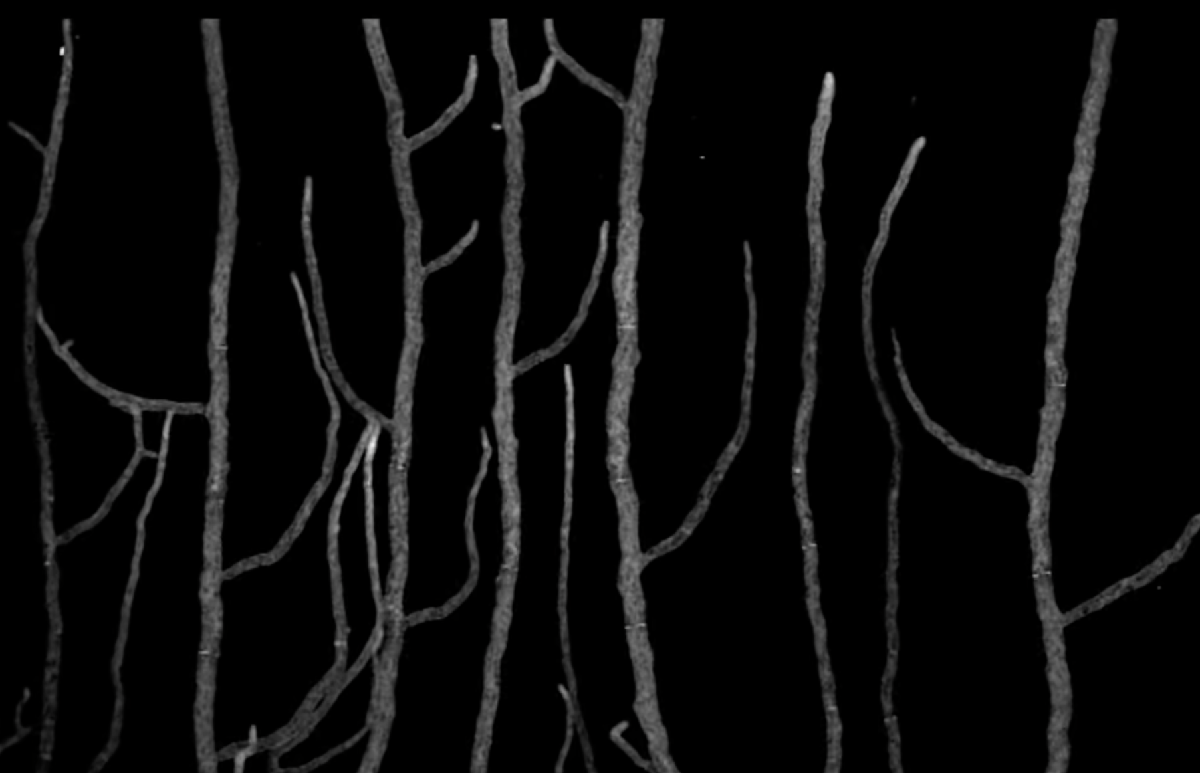

## Intro

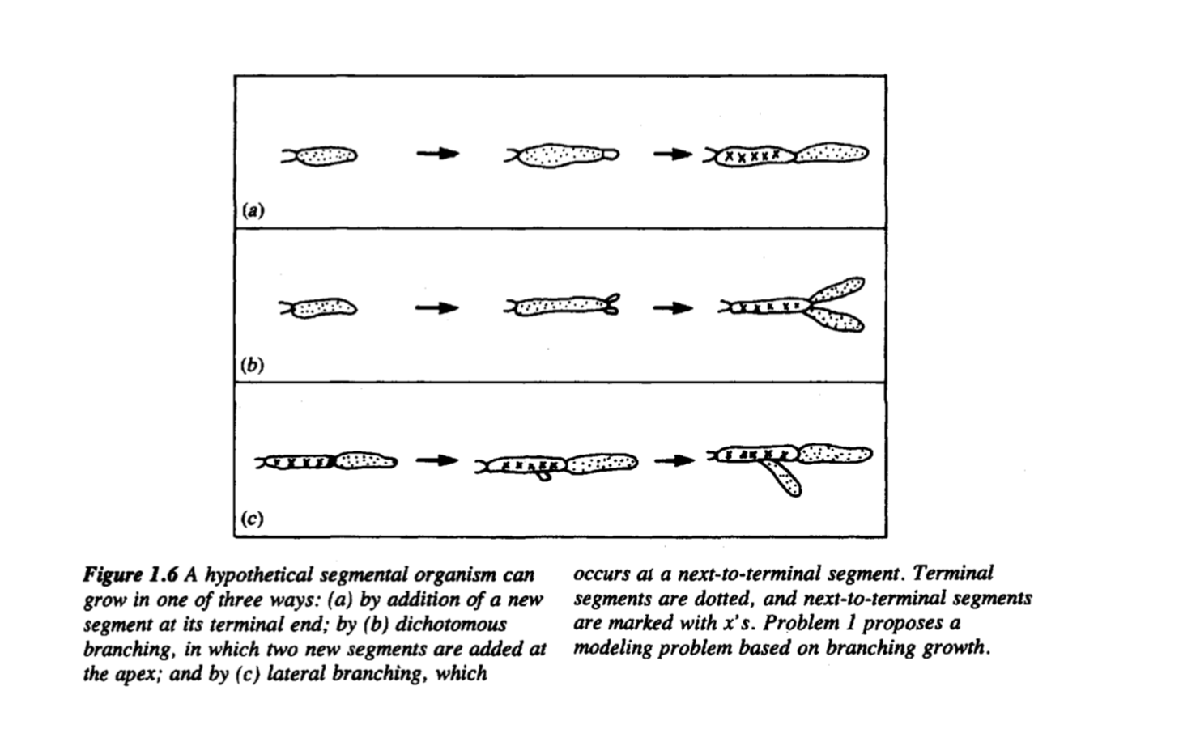

In this exercise, we consider modeling the growth of an oragnism that grows in segments, like some types of algae and fungi do.

In real life, the rate of growth of such organism can be highly complicated depending on the nutrients available and its environment. Here, we form a very simple model. The ogranism we are considering grows in form of additon of segments every 24 hours. The new segments are added in 3 possible ways:

- A terminal segment can produce 1 daughter with frequency $p$ (elongating).

- A terminal segment can produce 2 daughters (*dichotomous* branching) with frequency $q$.

- A next-to-terminal segment can produce 1 daughter (*lateral* branching) with frequency $r$.

The picture above shows each of these growth mechanisms. 

Here, we assume that all daughters are terminal segments. All terminal segments participate in each growth cycle ($p+q=1$) and become next-to-terminal segments in 1 generation. All next-to-terminal segments are replaced after each generation and no longer branch.  

We are interested in the number of terminal segments and total number of segments in the 10th generation.

## Set-Up

Like usual, first we set the parameters and unknowns. 

#### Scalars

Here, we specify the *branching* rates. 

q =0
p = 1 - q;
r = 1;

Then, we set the starting population, and we specify which generation (`n`) we are interested in: 

a00 = 0;
a0 = 2;
n = 5;

#### Vectors

In this problem, we need to store the information from 2 generations prior. For instance, to calculate `a_n(3),` the population of segment terminals at the third generation, we need `a_n(2) `and` a_n(1)`, the population of segment terminals at the second and first generation, respectively. The *vector *`a_n `is like our box of placeholders where we store additional information after each round of calculation:

a_n = zeros(n+2,1);
a_n(1) = a00;
a_n(2) = a0;

## Calculations

Here, for solving recursive relations, we will use a `for` loop. A `for` loop repeats (iterates over) a set of code for a specified number of times. 

#### Loops


for k = 3:1:n+2
    a_n(k) = (p+2*q)*a_n(k-1) + r*a_n(k-2);
end


## Plots

plot(0:1:n, a_n(2:end))
xlabel 'n'
ylabel 'a_n'
h = animatedline('MaximumNumPoints',100, 'Marker','h');
% axis([0,4*pi,-1,1])

x = linspace(0,n,n+1);
y = a_n(2:end);
for k = 1:length(x)
    addpoints(h,x(k),y(k));

grid on
% annotation('arrow',[0.8571 0.7661],[0.3157 0.4595])
    drawnow
end


total_population = sum(a_n, "all")
pop_at_generation_n = cumsum(a_n);
plot(0:1:n, pop_at_generation_n(2:end))
ylabel 'total population at nth generation'
xlabel 'n'


## Functions

function new_segments = reproduce(num_next_to_terminal_segments, num_terminal_segments,p,q,r)
    b = num_next_to_terminal_segments;
    a = num_terminal_segments;
    a_new = (p+2*q)*a + r*b;
    new_segments = a_new;
end


% h = animatedline('Marker','o');
% x = 0:n;
% y = a_n(2:end);
% addpoints(h,x,y)

This problem was adapted from ***Mathematical models in Biology*** by **Leah Edelstein-Keshet**.